clear all;
dataset = load("../data/dataset.mat");
addpath("../object_simulation/");
addpath("../linear_model/");
addpath("../nets/");
u_train = dataset.u_train;
y_train = dataset.y_train;
u_val = dataset.u_val;
y_val = dataset.y_val;

tau = 3;
nb = 4;
na = 2;

% run("../nets/chosen_arx_model_arx_training_bfgs/model.m");
run("../nets/chosen_oe_model_oe_training_bfgs/model.m");
% run("../nets/chosen_oe_model_oe_training_gradient_descent/model.m");

sigma_u = 0.001; sigma_y = 0.001;
kstart = 10; kend = 1000;

N = 10; Nu = 5; lambda = 1;

u(1:kend) = 0;
y_obj(1:kend) = 0;
y_set(1:kstart) = 0;
y_set(kstart+1:260) = 0.6;
y_set(261:510) = 0;
y_set(511:760) = -1.7;
y_set(761:kend) = 0.2;
x1km1=0; x2km1=0;

d = zeros(1,kend);

min_u = -1;
max_u = 1;


for k = kstart:kend

    [y_obj(k), x1km1, x2km1] = simulation_object(x1km1, x2km1, u(k-3));

    yk_model = y_nn_model(y_obj(k-1), y_obj(k-2), u(k-tau), u(k-nb), w20, w2, w10, w1);

    d(k)= y_obj(k) - yk_model;

    Y0 = zeros(N,1);

    for i=1:N

        if i < tau
            u1 = u(k-tau-1+i);
            u2 = u(k-nb-1+i);

        elseif i < nb
            u1 = u(k-1);
            u2 = u(k-nb-1+i);
        else 
            u1 = u(k-1);
            u2 = u(k-1);
        end 

         if i == 1
             y1 = y_obj(k);
             y2 = y_obj(k-1);

        elseif i == 2
            y1 = Y0(1);
            y2 = y_obj(k);
        else 
            y1 = Y0(i-1);
            y2 = Y0(i-2);
        end

        Y0(i) = y_nn_model(y1, y2, u1, u2, w20, w2, w10, w1) + d(k);
    end

    b1 = (y_nn_model(y_obj(k-1), y_obj(k-2), u(k-tau) + sigma_u, u(k-nb), w20, w2, w10, w1) - yk_model)/sigma_u;
    b2 = (y_nn_model(y_obj(k-1), y_obj(k-2), u(k-tau), u(k-nb) + sigma_u, w20, w2, w10, w1) - yk_model)/sigma_u;
    a1 = -(y_nn_model(y_obj(k-1) + sigma_y, y_obj(k-2), u(k-tau), u(k-nb), w20, w2, w10, w1) - yk_model)/sigma_y;
    a2 = -(y_nn_model(y_obj(k-1), y_obj(k-2)+ sigma_y, u(k-tau), u(k-nb), w20, w2, w10, w1) - yk_model)/sigma_y;

    K = get_K(a1, a2, b1, b2, tau, nb, N, Nu, lambda);

    Yset = y_set(k)*ones(N,1);
    delta_U = K*(Yset - Y0);
    delta_u = delta_U(1);

    u(k) = delta_u + u(k-1);
    u(k) = min(max(u(k), min_u), max_u);
end


E = sum((y_set - y_obj).^2)

E = 57.4849

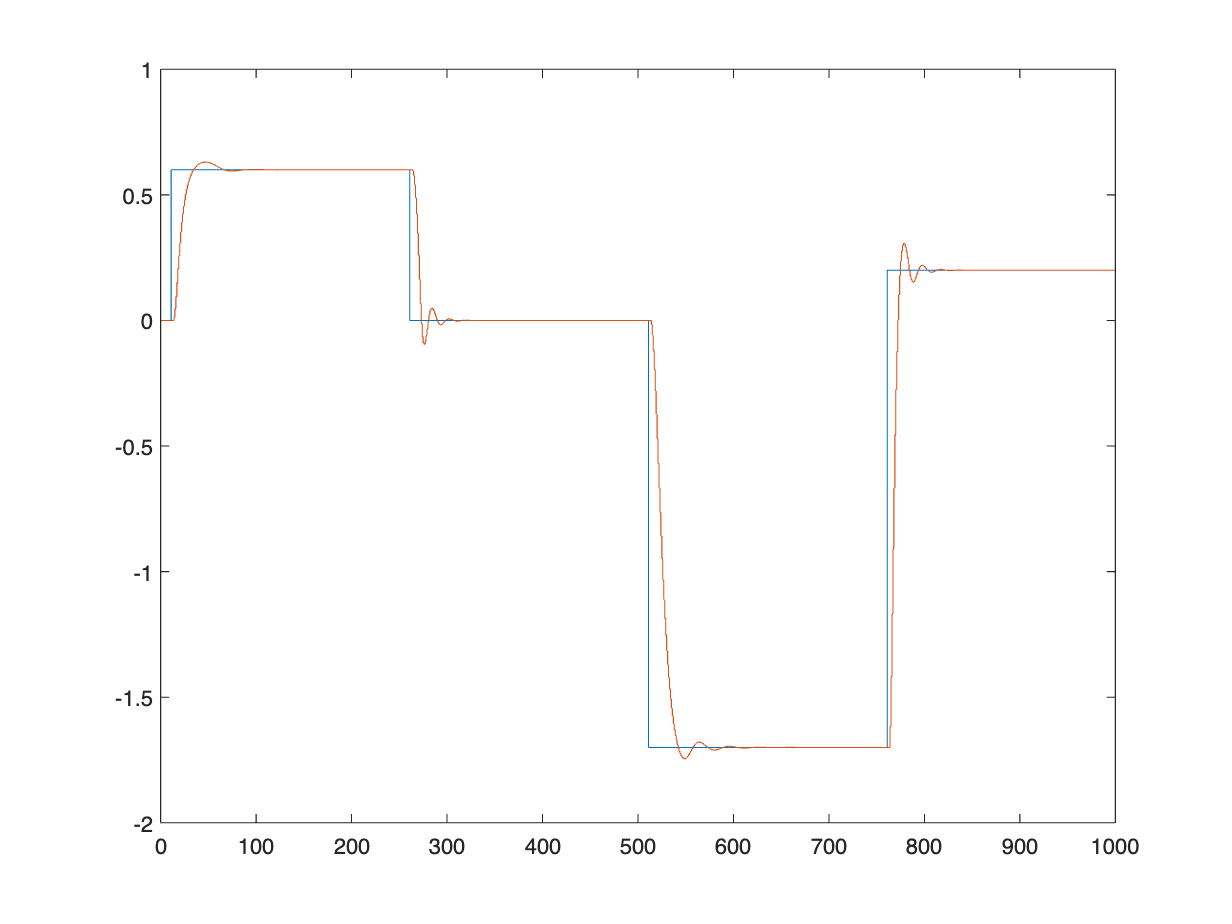


figure;
stairs(y_set);
hold on
stairs(y_obj);

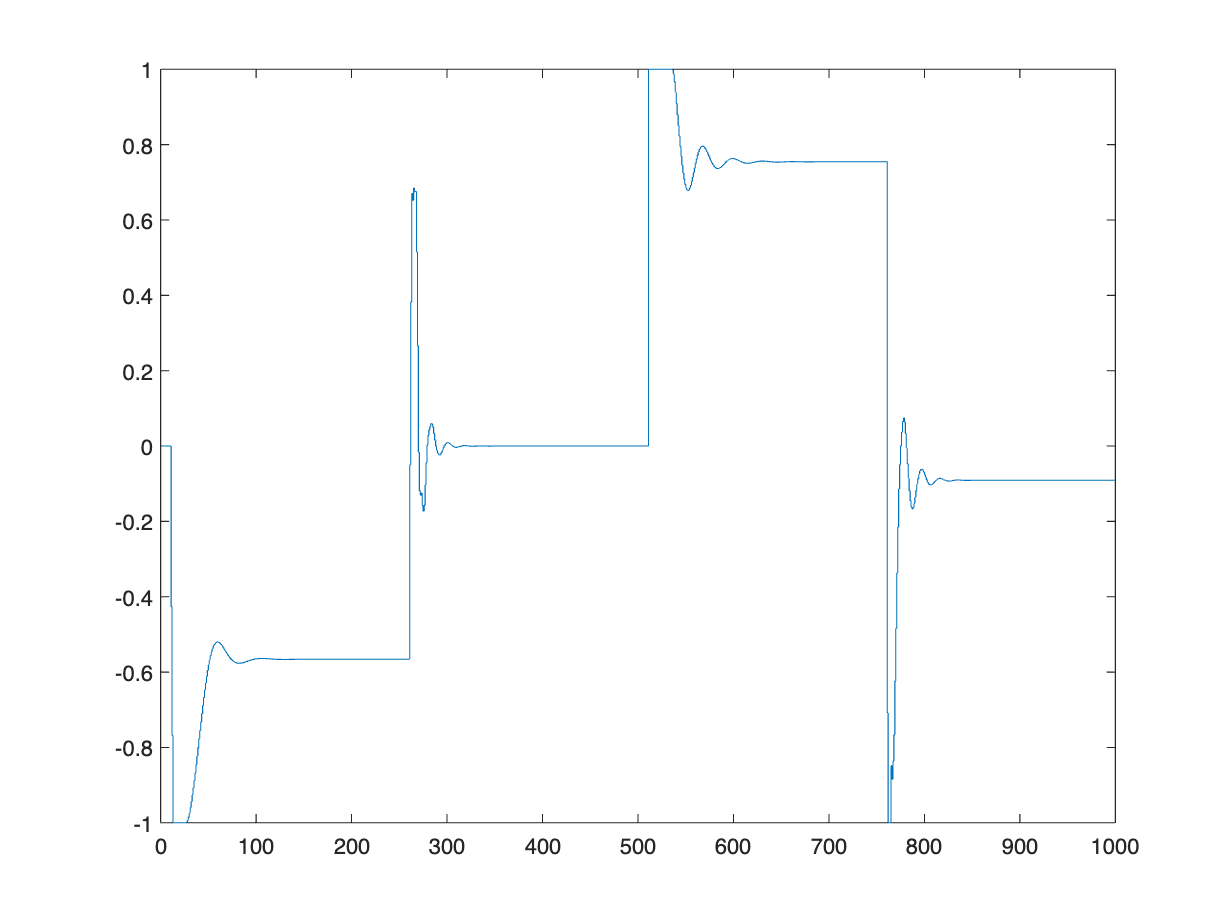

figure;
stairs(u);